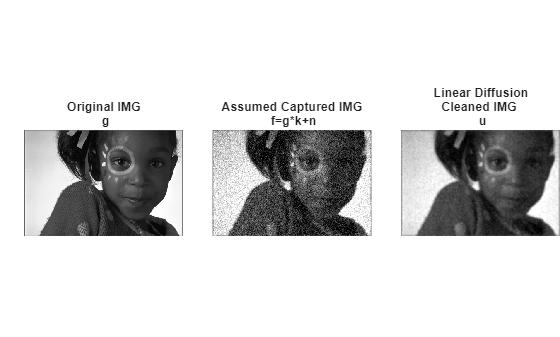

%I = loadImageFromSubfolder('Ex1', 'sun_girl.png');
clear;close all;clc;
g = im2double(imread("Ex1\sun_girl.png")); %0-1 grayscale

%We assume model of: f=g*k+n
t= 1;
sigma=sqrt(2*t);
ksize = 7;
noise_std = 0.1;
n = noise_std*randn(size(g));
%n = imgaussfilt(randn(size(g)), 1);

k = fspecial('gaussian',ksize,sigma);
f = imfilter(g,k,"symmetric","same","conv") + n;
u = f;
iter = 100;
dt = 0.01;
lambda=0.001;
[u, mean_vals, std_vals] = linearDiffusion(f,u,k,iter,dt,lambda);



figure;
titles = {"Original IMG\n g","Assumed Captured IMG\n f=g*k+n","Linear Diffusion\nCleaned IMG \n u"};
t = tiledlayout(1,3,'Padding','tight','TileSpacing','compact');
nexttile;  imshow(g); title(sprintf(titles{1}));
nexttile;  imshow(f); title(sprintf(titles{2}));
nexttile;  imshow(u); title(sprintf(titles{3}));

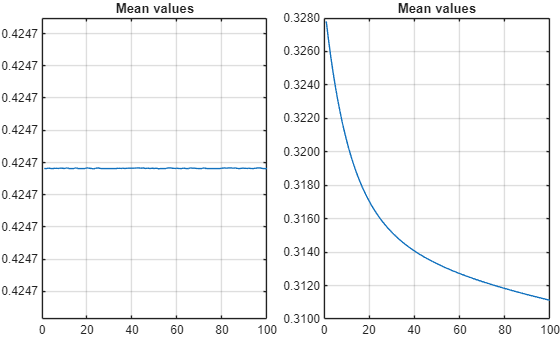


figure;
titles = {"Mean values","STD values"};
t = tiledlayout(1,2,'Padding','tight','TileSpacing','compact');
nexttile;  plot(mean_vals); title(sprintf(titles{1}));ytickformat("%.4f");grid on;
nexttile;  plot(std_vals); title(sprintf(titles{1}));ytickformat("%.4f");grid on;



function [u,mean_vals,std_vals] = linearDiffusion(f,u,k,iter,dt,lamda)
k_tilde = flipud(fliplr(k));
mean_vals = zeros(1,iter);
std_vals = zeros(1,iter);

for i=1:iter
[ux,uy] = grad(u);
u_t = div(ux,uy);
fidelity_t = imfilter((f-imfilter(u,k,'symmetric','same','conv')),k_tilde,"symmetric","same","conv");
u = u+dt.*(u_t+lamda*fidelity_t);
mean_vals(i)=mean(u(:));
std_vals(i)=std(u(:));
end

end


%in images we assume h=1
function [fx,fy] = grad(V)
%forward difference gradient
fx = V(:,[2:end,end])-V;%select all rows, and shift cols +1 right, and duplicate last col again so we get direlhe boundry of 0
fy = V([2:end,end],:)-V;
end

function bd = div(Vx,Vy)
%backward difference divergence
fx = Vx - Vx(:,[1,1:end-1]); fx(:,1)=Vx(:,1); fx(:,end)=-Vx(:,end-1);
fy = Vy - Vy([1,1:end-1],:); fy(1,:)=Vy(1,:); fy(end,:)=-Vy(end-1,:);
bd = fx + fy;
end



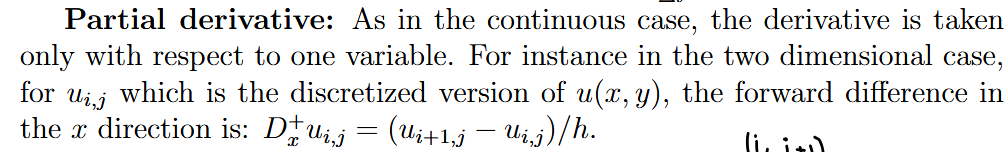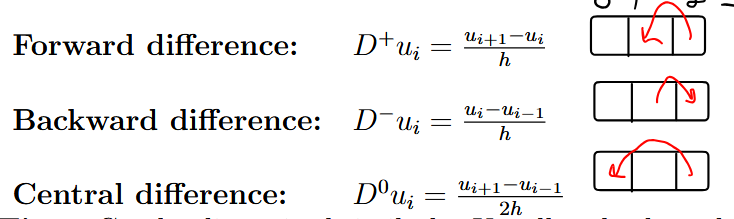

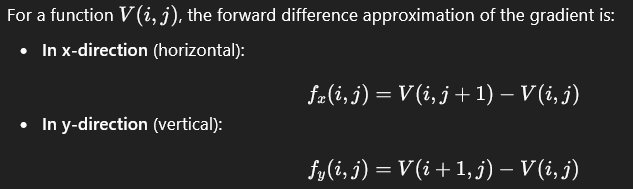

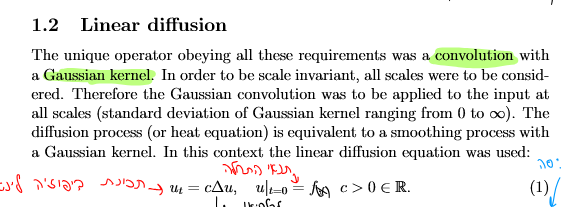

function img = loadImageFromSubfolder(subfolder, filename)
%LOADIMAGEFROMSUBFOLDER Load image from a subfolder relative to this .m file.
%
%   img = loadImageFromSubfolder(subfolder, filename)
%
%   Example:
%       img = loadImageFromSubfolder('images', 'cat.png');

    % Get the folder of the caller .m file
    baseFolder = fileparts(mfilename('fullpath'));

    % Construct full path to the subfolder
    targetFolder = fullfile(baseFolder, subfolder);

    % Construct full path to the image file
    imgPath = fullfile(targetFolder, filename);

    % Check if the file exists
    if ~isfile(imgPath)
        error('File not found: %s', imgPath);
    end

    % Read the image
    img = imread(imgPath);
end
